### Step a:

Draw a set of transfer functions that can be used to create a rendering of a CT dataset of the abdomen. Assume that the signal in CT units from bone is >80, that from liver is 25-50 and that the signal from fat is 10-25. The tissues appear semi-realistic, i.e. bone should be white and opaque, liver should be dark red and opaque, fat should be white and semi-transparent.

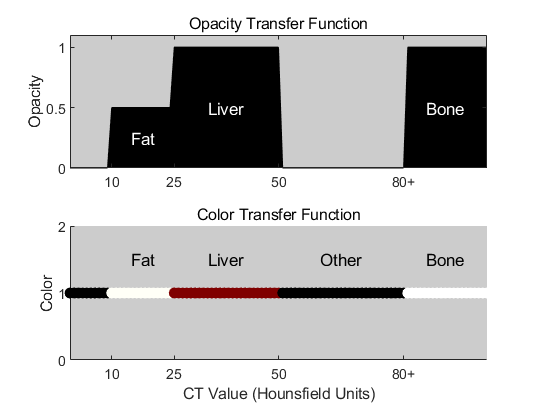

% Define CT value ranges
ct_values = 0:100;
colors = zeros(length(ct_values), 3);
opacities = zeros(length(ct_values), 1);

% Mapping CT values to colors and opacities
for i = 1:length(ct_values)
    if ct_values(i) > 80  % Bone
        colors(i, :) = [1, 1, 1];
        opacities(i) = 1.0;
    elseif ct_values(i) >= 25 && ct_values(i) <= 50  % Liver
        colors(i, :) = [0.5, 0, 0];
        opacities(i) = 1.0;
    elseif ct_values(i) >= 10 && ct_values(i) <= 25  % Fat
        colors(i, :) = [1, 1, 0.97];
        opacities(i) = 0.5;
    else  % Other tissues
        colors(i, :) = [0, 0, 0];  % Black (invisible)
        opacities(i) = 0.0;  % Transparent
    end
end

% Plotting
figure;
subplot(2,1,1);
area(ct_values, opacities, 'FaceColor', 'k');
ylabel('Opacity');
title('Opacity Transfer Function');
ylim([0 1.1]);
set(gca, 'XTick', [10, 25, 50, 80], 'XTickLabel', {'10', '25', '50', '80+'});
text(17.5, 0.25, 'Fat', 'HorizontalAlignment', 'center', 'Color', 'white');
text(37.5, 0.5, 'Liver', 'HorizontalAlignment', 'center', 'Color', 'white');
text(90, 0.5, 'Bone', 'HorizontalAlignment', 'center', 'Color', 'white');

subplot(2,1,2);
hold on;
for i = 1:length(ct_values)
    plot(ct_values(i), 1, 'o', 'Color', colors(i, :), 'MarkerFaceColor', colors(i, :));
end
ylabel('Color');
title('Color Transfer Function');
ylim([0 2]);
xlabel('CT Value (Hounsfield Units)');
set(gca, 'XTick', [10, 25, 50, 80], 'XTickLabel', {'10', '25', '50', '80+'});
text(17.5, 1.5, 'Fat', 'HorizontalAlignment', 'center', 'Color', 'black');
text(37.5, 1.5, 'Liver', 'HorizontalAlignment', 'center', 'Color', 'black');
text(65, 1.5, 'Other', 'HorizontalAlignment', 'center', 'Color', 'black');
text(90, 1.5, 'Bone', 'HorizontalAlignment', 'center', 'Color', 'black');

% Set background colors to gray
set(gca, 'Color', [0.8 0.8 0.8]);
set(findobj(gcf, 'Type', 'axes'), 'Color', [0.8 0.8 0.8]);

### Step b:

In the provided coursework datasets, you can find the optical projection tomography volumetric data of a zebrafish. Implement the MIP method and apply it to project the volumetric data along the 3 orthogonal directions (x, y and z-axis). Display each projection plane of your rendering.

% Specify the directory containing the TIFF files
folderPath = './zfish_embryo_8bit';
tifFiles = dir(fullfile(folderPath, '*.tif'));  % List all .tif files in the folder

% Preallocate a 3D matrix based on the number of files and image dimensions
exampleImage = imread(fullfile(folderPath, tifFiles(1).name));
volume = zeros(size(exampleImage, 1), size(exampleImage, 2), length(tifFiles), 'like', exampleImage);

% Load each slice into the volume matrix
for k = 1:length(tifFiles)
    volume(:, :, k) = imread(fullfile(folderPath, tifFiles(k).name));
end

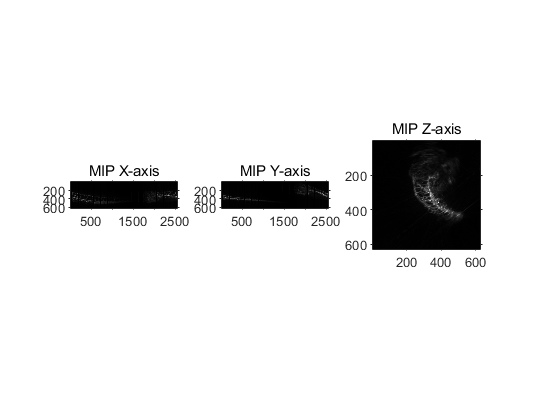

% Calculate MIPs
mipX = squeeze(max(volume, [], 1));
mipY = squeeze(max(volume, [], 2));
mipZ = squeeze(max(volume, [], 3));

% Display each MIP
figure;
subplot(1, 3, 1);
imshow(mipX, []);
title('MIP X-axis');

subplot(1, 3, 2);
imshow(mipY, []);
title('MIP Y-axis');

subplot(1, 3, 3);
imshow(mipZ, []);
title('MIP Z-axis');

% Apply swapping
mipX = swapHalves(mipX);

mipY = swapHalves(mipY);

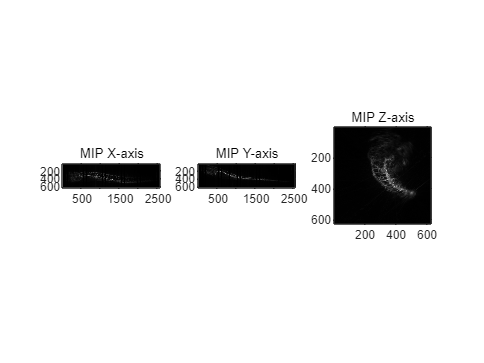


% Display swapped MIPs
figure;
subplot(1, 3, 1);
imshow(mipX, []);
title('MIP X-axis');

subplot(1, 3, 2);
imshow(mipY, []);
title('MIP Y-axis');

subplot(1, 3, 3);
imshow(mipZ, []);
title('MIP Z-axis');

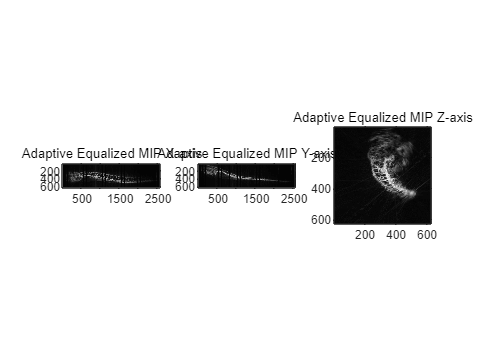

mipX = adapthisteq(mipX);
mipY = adapthisteq(mipY);
mipZ = adapthisteq(mipZ);

% Display adaptively equalized MIPs
figure;
subplot(1, 3, 1);
imshow(mipX);
title('Adaptive Equalized MIP X-axis');

subplot(1, 3, 2);
imshow(mipY);
title('Adaptive Equalized MIP Y-axis');

subplot(1, 3, 3);
imshow(mipZ);
title('Adaptive Equalized MIP Z-axis');

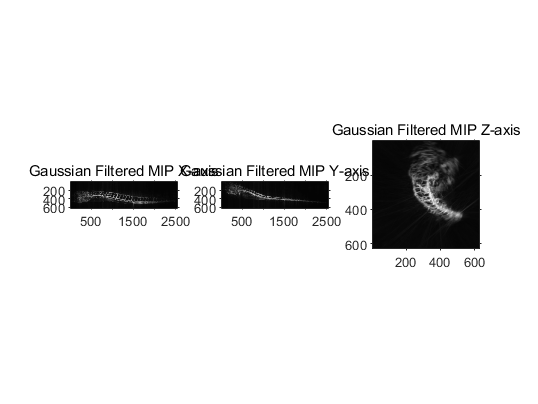

mipX = imgaussfilt(mipX, 2);  % Gaussian filter with sigma = 2
mipY = imgaussfilt(mipY, 2);
mipZ = imgaussfilt(mipZ, 2);

figure;
subplot(1, 3, 1);
imshow(mipX);
title('Gaussian Filtered MIP X-axis');

subplot(1, 3, 2);
imshow(mipY);
title('Gaussian Filtered MIP Y-axis');

subplot(1, 3, 3);
imshow(mipZ);
title('Gaussian Filtered MIP Z-axis');

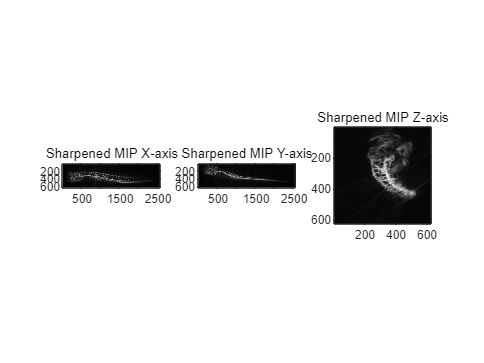

mipX = imsharpen(mipX);
mipY = imsharpen(mipY);
mipZ = imsharpen(mipZ);

figure;
subplot(1, 3, 1);
imshow(mipX);
title('Sharpened MIP X-axis');

subplot(1, 3, 2);
imshow(mipY);
title('Sharpened MIP Y-axis');

subplot(1, 3, 3);
imshow(mipZ);
title('Sharpened MIP Z-axis');

function output = swapHalves(img)
    midPoint = size(img, 2) / 2;
    leftHalf = img(:, 1:midPoint+350);
    rightHalf = img(:, midPoint+1+350:end);
    output = [rightHalf leftHalf];
end